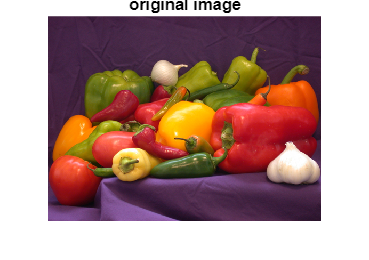

clc ;
clear all;
var_img = imread ("peppers.png");
imshow (var_img) ;
title ('original image');

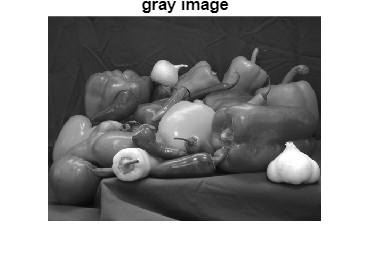

img_gray = rgb2gray(var_img);
imshow (img_gray);
title ('gray image');

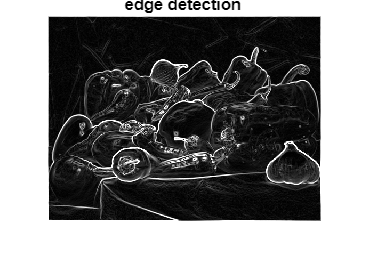



red = var_img (:,:,1);
green = var_img (:,:,2);
blue = var_img (:,:,3);




kx = [-1 0 1 ;
      -2 0 2 ;
      -1 0 1 ; ]; 
ky = [ -1 -2 -1;
        0 0 0 ;
        1 2 1 ;];
vertical = conv2(img_gray,kx,'same');
horizontal = conv2(img_gray,ky,'same');

edge = sqrt(vertical.^2 + horizontal .^2);
img_edge_detection = uint16(edge);
imshow (img_edge_detection);
title ('edge detection ');

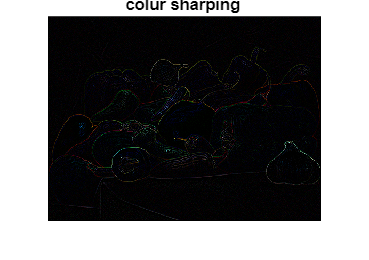








kx_sharp = [  0 1 0 ;
             1 -4 1 ;
              0 1 0 ; ]; 


colur_red = conv2(red,kx_sharp,'same');
colur_green = conv2(green,kx_sharp,'same');
colur_blue = conv2(blue,kx_sharp,'same');


colur_sharping = uint16(cat(3,colur_red,colur_green,colur_blue));

imshow (colur_sharping); 
title ('colur sharping ');

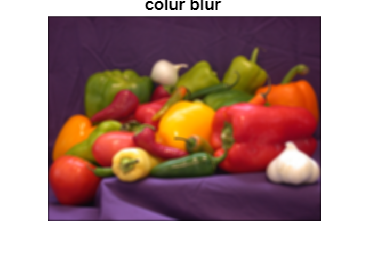










k_average = ones(7) / 49 ;

colur_red1 = conv2(red,k_average,'same');
colur_green1 = conv2(green,k_average,'same');
colur_blue1 = conv2(blue,k_average,'same');

colur_blur = uint16(cat(3,colur_red1,colur_green1,colur_blue1));

imshow (colur_blur); 
title ('colur blur ');

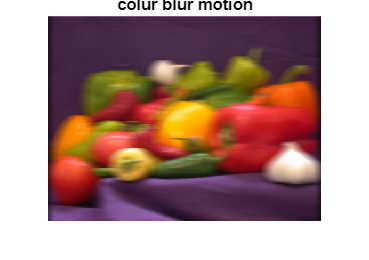






k_blur_motion_horizontal = zeros(25);
k_blur_motion_horizontal (13,:) = 1/25;


colur_red2 = conv2(red,k_blur_motion_horizontal,'same');
colur_green2 = conv2(green,k_blur_motion_horizontal,'same');
colur_blue2 = conv2(blue,k_blur_motion_horizontal,'same');

colur_blur_motion = uint16(cat(3,colur_red2,colur_green2,colur_blue2));

imshow (colur_blur_motion);
title ('colur blur motion');

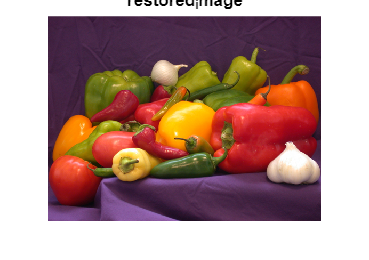




original_image=var_img;
motion_kernel= ones(1,30)/30;

motional_image(:,:,1) = (conv2(original_image(:,:,1),motion_kernel));
motional_image(:,:,2) = (conv2(original_image(:,:,2),motion_kernel));
motional_image(:,:,3) = (conv2(original_image(:,:,3),motion_kernel));

motion_kernel_ft=fft2(motion_kernel,size(motional_image,1),size(motional_image,2));

motional_image_ft=fft2(motional_image);

epsilon=.00001;
image_restored_ft =motional_image_ft ./(motion_kernel_ft+epsilon);

restored_image = abs(ifft2(image_restored_ft));

restored_image =restored_image(1:size(original_image,1),1:size(original_image,2),1:size(original_image,3));
motional_image =motional_image(1:size(original_image,1),25:size(original_image,2),1:size(original_image,3));



  imshow(uint16(restored_image));
  title ('restored_image');